# Assignment 2 - Simple Mechanism

% Hands on solution for Simple Mechanism task
clear;
% u = [phi_2; d];
a = 0.1;
b = 0.2;
omega = 1;
phi = @(t) pi/6 + omega*t;

% set a reasonable starting point
u0 = [0; b + a];

eps = 1e-9;
t= linspace (0,1,101);
results = zeros(length(t),5);


for i=1:length(t)
    syms t_sym;
    % create function handles
    F = @(u) constraint(u, a, b, phi(i));
    J = @(u) jacobian(u, b);
    [u, iteration_counter] = NR_method(F, J, u0, eps);

    x_prime = - J(u);
    fprintf('\n\tMechanism valid position is for d = %.3g m and theta = %g deg\n\n', ...
        u(2), rad2deg(u(1)));
    fprintf('\n\tTime derivatives: d_dot = %.3g and theta_dot = %g \n\n', ...
         x_prime(2), rad2deg(x_prime(1)));
    u0 = u;
    results(i,1) = i;
    results(i,2) = u(2);
    results(i,3) = x_prime(2);
    results(i,4) = u(1);
    results(i,5) = rad2deg(x_prime(1));
end


	Mechanism valid position is for d = 0.178 m and theta = 29.9632 deg




	Time derivatives: d_dot = 0.173 and theta_dot = 5.7232 




	Mechanism valid position is for d = 0.11 m and theta = 16.84 deg




	Time derivatives: d_dot = 0.191 and theta_dot = 3.31972 




	Mechanism valid position is for d = 0.104 m and theta = -10.7423 deg




	Time derivatives: d_dot = 0.196 and theta_dot = -2.13589 




	Mechanism valid position is for d = 0.155 m and theta = -29.414 deg




	Time derivatives: d_dot = 0.174 and theta_dot = -5.62777 




	Mechanism valid position is for d = 0.26 m and theta = -20.1397 deg




	Time derivatives: d_dot = 0.188 and theta_dot = -3.94551 




	Mechanism valid position is for d = 0.296 m and theta = 6.8374 deg




	Time derivatives: d_dot = 0.199 and theta_dot = 1.36424 




	Mechanism valid position is for d = 0.209 m and theta = 28.2266 deg




	Time derivatives: d_dot = 0.176 and theta_dot = 5.41971 




	Mechanism valid position is for d = 0.122 m and theta = 23.0809 deg




	Time derivatives: d_dot = 0.184 and theta_dot = 4.49233 




	Mechanism valid position is for d = 0.1 m and theta = -2.82755 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.56528 




	Mechanism valid position is for d = 0.134 m and theta = -26.4448 deg




	Time derivatives: d_dot = 0.179 and theta_dot = -5.10317 




	Mechanism valid position is for d = 0.231 m and theta = -25.5883 deg




	Time derivatives: d_dot = 0.18 and theta_dot = -4.94923 




	Mechanism valid position is for d = 0.3 m and theta = -1.22504 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.24499 




	Mechanism valid position is for d = 0.24 m and theta = 24.1294 deg




	Time derivatives: d_dot = 0.183 and theta_dot = 4.6845 




	Mechanism valid position is for d = 0.14 m and theta = 27.5893 deg




	Time derivatives: d_dot = 0.177 and theta_dot = 5.30708 




	Mechanism valid position is for d = 0.101 m and theta = 5.25917 deg




	Time derivatives: d_dot = 0.199 and theta_dot = 1.05036 




	Mechanism valid position is for d = 0.118 m and theta = -21.351 deg




	Time derivatives: d_dot = 0.186 and theta_dot = -4.17206 




	Mechanism valid position is for d = 0.199 m and theta = -29.0182 deg




	Time derivatives: d_dot = 0.175 and theta_dot = -5.5587 




	Mechanism valid position is for d = 0.292 m and theta = -9.21316 deg




	Time derivatives: d_dot = 0.197 and theta_dot = -1.8347 




	Mechanism valid position is for d = 0.268 m and theta = 18.1843 deg




	Time derivatives: d_dot = 0.19 and theta_dot = 3.57611 




	Mechanism valid position is for d = 0.163 m and theta = 29.824 deg




	Time derivatives: d_dot = 0.174 and theta_dot = 5.69907 




	Mechanism valid position is for d = 0.106 m and theta = 13.0235 deg




	Time derivatives: d_dot = 0.195 and theta_dot = 2.58232 




	Mechanism valid position is for d = 0.107 m and theta = -14.7038 deg




	Time derivatives: d_dot = 0.193 and theta_dot = -2.9086 




	Mechanism valid position is for d = 0.169 m and theta = -29.9757 deg




	Time derivatives: d_dot = 0.173 and theta_dot = -5.72537 




	Mechanism valid position is for d = 0.274 m and theta = -16.6235 deg




	Time derivatives: d_dot = 0.192 and theta_dot = -3.27826 




	Mechanism valid position is for d = 0.289 m and theta = 10.9814 deg




	Time derivatives: d_dot = 0.196 and theta_dot = 2.18286 




	Mechanism valid position is for d = 0.192 m and theta = 29.4673 deg




	Time derivatives: d_dot = 0.174 and theta_dot = 5.63707 




	Mechanism valid position is for d = 0.115 m and theta = 19.9432 deg




	Time derivatives: d_dot = 0.188 and theta_dot = 3.90858 




	Mechanism valid position is for d = 0.102 m and theta = -7.08524 deg




	Time derivatives: d_dot = 0.198 and theta_dot = -1.41344 




	Mechanism valid position is for d = 0.144 m and theta = -28.3187 deg




	Time derivatives: d_dot = 0.176 and theta_dot = -5.43595 




	Mechanism valid position is for d = 0.247 m and theta = -22.9089 deg




	Time derivatives: d_dot = 0.184 and theta_dot = -4.46068 




	Mechanism valid position is for d = 0.299 m and theta = 3.08011 deg




	Time derivatives: d_dot = 0.2 and theta_dot = 0.615725 




	Mechanism valid position is for d = 0.224 m and theta = 26.5725 deg




	Time derivatives: d_dot = 0.179 and theta_dot = 5.12603 




	Mechanism valid position is for d = 0.129 m and theta = 25.4457 deg




	Time derivatives: d_dot = 0.181 and theta_dot = 4.92349 




	Mechanism valid position is for d = 0.1 m and theta = 0.971609 deg




	Time derivatives: d_dot = 0.2 and theta_dot = 0.194312 




	Mechanism valid position is for d = 0.125 m and theta = -24.2885 deg




	Time derivatives: d_dot = 0.182 and theta_dot = -4.71351 




	Mechanism valid position is for d = 0.216 m and theta = -27.4803 deg




	Time derivatives: d_dot = 0.177 and theta_dot = -5.28776 




	Mechanism valid position is for d = 0.298 m and theta = -5.00868 deg




	Time derivatives: d_dot = 0.199 and theta_dot = -1.00046 




	Mechanism valid position is for d = 0.254 m and theta = 21.5369 deg




	Time derivatives: d_dot = 0.186 and theta_dot = 4.20665 




	Mechanism valid position is for d = 0.15 m and theta = 28.9467 deg




	Time derivatives: d_dot = 0.175 and theta_dot = 5.54619 




	Mechanism valid position is for d = 0.103 m and theta = 8.96952 deg




	Time derivatives: d_dot = 0.198 and theta_dot = 1.78658 




	Mechanism valid position is for d = 0.112 m and theta = -18.3922 deg




	Time derivatives: d_dot = 0.19 and theta_dot = -3.6156 




	Mechanism valid position is for d = 0.185 m and theta = -29.7926 deg




	Time derivatives: d_dot = 0.174 and theta_dot = -5.69362 




	Mechanism valid position is for d = 0.285 m and theta = -12.7907 deg




	Time derivatives: d_dot = 0.195 and theta_dot = -2.53695 




	Mechanism valid position is for d = 0.279 m and theta = 14.9292 deg




	Time derivatives: d_dot = 0.193 and theta_dot = 2.95218 




	Mechanism valid position is for d = 0.176 m and theta = 29.9856 deg




	Time derivatives: d_dot = 0.173 and theta_dot = 5.72709 




	Mechanism valid position is for d = 0.109 m and theta = 16.406 deg




	Time derivatives: d_dot = 0.192 and theta_dot = 3.23654 




	Mechanism valid position is for d = 0.104 m and theta = -11.2199 deg




	Time derivatives: d_dot = 0.196 and theta_dot = -2.22967 




	Mechanism valid position is for d = 0.157 m and theta = -29.5182 deg




	Time derivatives: d_dot = 0.174 and theta_dot = -5.64593 




	Mechanism valid position is for d = 0.262 m and theta = -19.7453 deg




	Time derivatives: d_dot = 0.188 and theta_dot = -3.87135 




	Mechanism valid position is for d = 0.295 m and theta = 7.33265 deg




	Time derivatives: d_dot = 0.198 and theta_dot = 1.46253 




	Mechanism valid position is for d = 0.207 m and theta = 28.4086 deg




	Time derivatives: d_dot = 0.176 and theta_dot = 5.45177 




	Mechanism valid position is for d = 0.121 m and theta = 22.7353 deg




	Time derivatives: d_dot = 0.184 and theta_dot = 4.42867 




	Mechanism valid position is for d = 0.1 m and theta = -3.33249 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.666122 




	Mechanism valid position is for d = 0.135 m and theta = -26.6982 deg




	Time derivatives: d_dot = 0.179 and theta_dot = -5.14849 




	Mechanism valid position is for d = 0.233 m and theta = -25.3011 deg




	Time derivatives: d_dot = 0.181 and theta_dot = -4.89736 




	Mechanism valid position is for d = 0.3 m and theta = -0.718117 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.14362 




	Mechanism valid position is for d = 0.238 m and theta = 24.4458 deg




	Time derivatives: d_dot = 0.182 and theta_dot = 4.74216 




	Mechanism valid position is for d = 0.138 m and theta = 27.3691 deg




	Time derivatives: d_dot = 0.178 and theta_dot = 5.26802 




	Mechanism valid position is for d = 0.101 m and theta = 4.7579 deg




	Time derivatives: d_dot = 0.199 and theta_dot = 0.950486 




	Mechanism valid position is for d = 0.119 m and theta = -21.7212 deg




	Time derivatives: d_dot = 0.186 and theta_dot = -4.24092 




	Mechanism valid position is for d = 0.201 m and theta = -28.8728 deg




	Time derivatives: d_dot = 0.175 and theta_dot = -5.53324 




	Mechanism valid position is for d = 0.293 m and theta = -8.72533 deg




	Time derivatives: d_dot = 0.198 and theta_dot = -1.73833 




	Mechanism valid position is for d = 0.267 m and theta = 18.5989 deg




	Time derivatives: d_dot = 0.19 and theta_dot = 3.6548 




	Mechanism valid position is for d = 0.162 m and theta = 29.7586 deg




	Time derivatives: d_dot = 0.174 and theta_dot = 5.68772 




	Mechanism valid position is for d = 0.105 m and theta = 12.5572 deg




	Time derivatives: d_dot = 0.195 and theta_dot = 2.49138 




	Mechanism valid position is for d = 0.108 m and theta = -15.1537 deg




	Time derivatives: d_dot = 0.193 and theta_dot = -2.99552 




	Mechanism valid position is for d = 0.171 m and theta = -29.993 deg




	Time derivatives: d_dot = 0.173 and theta_dot = -5.72836 




	Mechanism valid position is for d = 0.275 m and theta = -16.1873 deg




	Time derivatives: d_dot = 0.192 and theta_dot = -3.19456 




	Mechanism valid position is for d = 0.288 m and theta = 11.4577 deg




	Time derivatives: d_dot = 0.196 and theta_dot = 2.2763 




	Mechanism valid position is for d = 0.19 m and theta = 29.5666 deg




	Time derivatives: d_dot = 0.174 and theta_dot = 5.65434 




	Mechanism valid position is for d = 0.114 m and theta = 19.546 deg




	Time derivatives: d_dot = 0.188 and theta_dot = 3.83381 




	Mechanism valid position is for d = 0.102 m and theta = -7.57963 deg




	Time derivatives: d_dot = 0.198 and theta_dot = -1.51151 




	Mechanism valid position is for d = 0.146 m and theta = -28.4961 deg




	Time derivatives: d_dot = 0.176 and theta_dot = -5.46715 




	Mechanism valid position is for d = 0.249 m and theta = -22.56 deg




	Time derivatives: d_dot = 0.185 and theta_dot = -4.39632 




	Mechanism valid position is for d = 0.299 m and theta = 3.58467 deg




	Time derivatives: d_dot = 0.2 and theta_dot = 0.716466 




	Mechanism valid position is for d = 0.222 m and theta = 26.8216 deg




	Time derivatives: d_dot = 0.178 and theta_dot = 5.17054 




	Mechanism valid position is for d = 0.128 m and theta = 25.1545 deg




	Time derivatives: d_dot = 0.181 and theta_dot = 4.87084 




	Mechanism valid position is for d = 0.1 m and theta = 0.464584 deg




	Time derivatives: d_dot = 0.2 and theta_dot = 0.0929157 




	Mechanism valid position is for d = 0.126 m and theta = -24.6012 deg




	Time derivatives: d_dot = 0.182 and theta_dot = -4.77044 




	Mechanism valid position is for d = 0.218 m and theta = -27.2558 deg




	Time derivatives: d_dot = 0.178 and theta_dot = -5.24787 




	Mechanism valid position is for d = 0.298 m and theta = -4.50683 deg




	Time derivatives: d_dot = 0.199 and theta_dot = -0.900438 




	Mechanism valid position is for d = 0.252 m and theta = 21.9039 deg




	Time derivatives: d_dot = 0.186 and theta_dot = 4.27485 




	Mechanism valid position is for d = 0.148 m and theta = 28.7964 deg




	Time derivatives: d_dot = 0.175 and theta_dot = 5.51987 




	Mechanism valid position is for d = 0.102 m and theta = 8.48062 deg




	Time derivatives: d_dot = 0.198 and theta_dot = 1.68994 




	Mechanism valid position is for d = 0.113 m and theta = -18.8043 deg




	Time derivatives: d_dot = 0.189 and theta_dot = -3.69371 




	Mechanism valid position is for d = 0.187 m and theta = -29.7221 deg




	Time derivatives: d_dot = 0.174 and theta_dot = -5.68138 




	Mechanism valid position is for d = 0.286 m and theta = -12.3228 deg




	Time derivatives: d_dot = 0.195 and theta_dot = -2.44561 




	Mechanism valid position is for d = 0.278 m and theta = 15.3771 deg




	Time derivatives: d_dot = 0.193 and theta_dot = 3.03864 




	Mechanism valid position is for d = 0.174 m and theta = 29.9977 deg




	Time derivatives: d_dot = 0.173 and theta_dot = 5.72918 




	Mechanism valid position is for d = 0.109 m and theta = 15.9676 deg




	Time derivatives: d_dot = 0.192 and theta_dot = 3.15234 




	Mechanism valid position is for d = 0.104 m and theta = -11.6948 deg




	Time derivatives: d_dot = 0.196 and theta_dot = -2.32275 




	Mechanism valid position is for d = 0.159 m and theta = -29.6124 deg




	Time derivatives: d_dot = 0.174 and theta_dot = -5.66231 




	Mechanism valid position is for d = 0.264 m and theta = -19.3453 deg




	Time derivatives: d_dot = 0.189 and theta_dot = -3.79597 




	Mechanism valid position is for d = 0.294 m and theta = 7.82614 deg




	Time derivatives: d_dot = 0.198 and theta_dot = 1.56037 




	Mechanism valid position is for d = 0.205 m and theta = 28.5812 deg




	Time derivatives: d_dot = 0.176 and theta_dot = 5.48211 




	Mechanism valid position is for d = 0.12 m and theta = 22.3831 deg




	Time derivatives: d_dot = 0.185 and theta_dot = 4.36363 




	Mechanism valid position is for d = 0.1 m and theta = -3.83664 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.766754 




	Mechanism valid position is for d = 0.136 m and theta = -26.943 deg




	Time derivatives: d_dot = 0.178 and theta_dot = -5.19219 




	Mechanism valid position is for d = 0.235 m and theta = -25.0061 deg




	Time derivatives: d_dot = 0.181 and theta_dot = -4.84395 




	Mechanism valid position is for d = 0.3 m and theta = -0.211023 deg




	Time derivatives: d_dot = 0.2 and theta_dot = -0.0422045 




	Mechanism valid position is for d = 0.236 m and theta = 24.7547 deg




	Time derivatives: d_dot = 0.182 and theta_dot = 4.79834 



disp(results)

    1.0000    0.1780    0.1733    0.5230    5.7232
    2.0000    0.1099    0.1914    0.2939    3.3197
    3.0000    0.1037    0.1965   -0.1875   -2.1359
    4.0000    0.1555    0.1742   -0.5134   -5.6278
    5.0000    0.2603    0.1878   -0.3515   -3.9455
    6.0000    0.2957    0.1986    0.1193    1.3642
    7.0000    0.2087    0.1762    0.4926    5.4197
    8.0000    0.1219    0.1840    0.4028    4.4923
    9.0000    0.1002    0.1998   -0.0494   -0.5653
   10.0000    0.1336    0.1791   -0.4615   -5.1032
   11.0000    0.2308    0.1804   -0.4466   -4.9492
   12.0000    0.2999    0.2000   -0.0214   -0.2450
   13.0000    0.2401    0.1825    0.4211    4.6845
   14.0000    0.1396    0.1773    0.4815    5.3071
   15.0000    0.1009    0.1992    0.0918    1.0504
   16.0000    0.1177    0.1863   -0.3726   -4.1721
   17.0000    0.1991    0.1749   -0.5065   -5.5587
   18.0000    0.2922    0.1974   -0.1608   -1.8347
   19.0000    0.2681    0.1900    0.3174    3.5761
   20.0000    0.1632    0.1735 

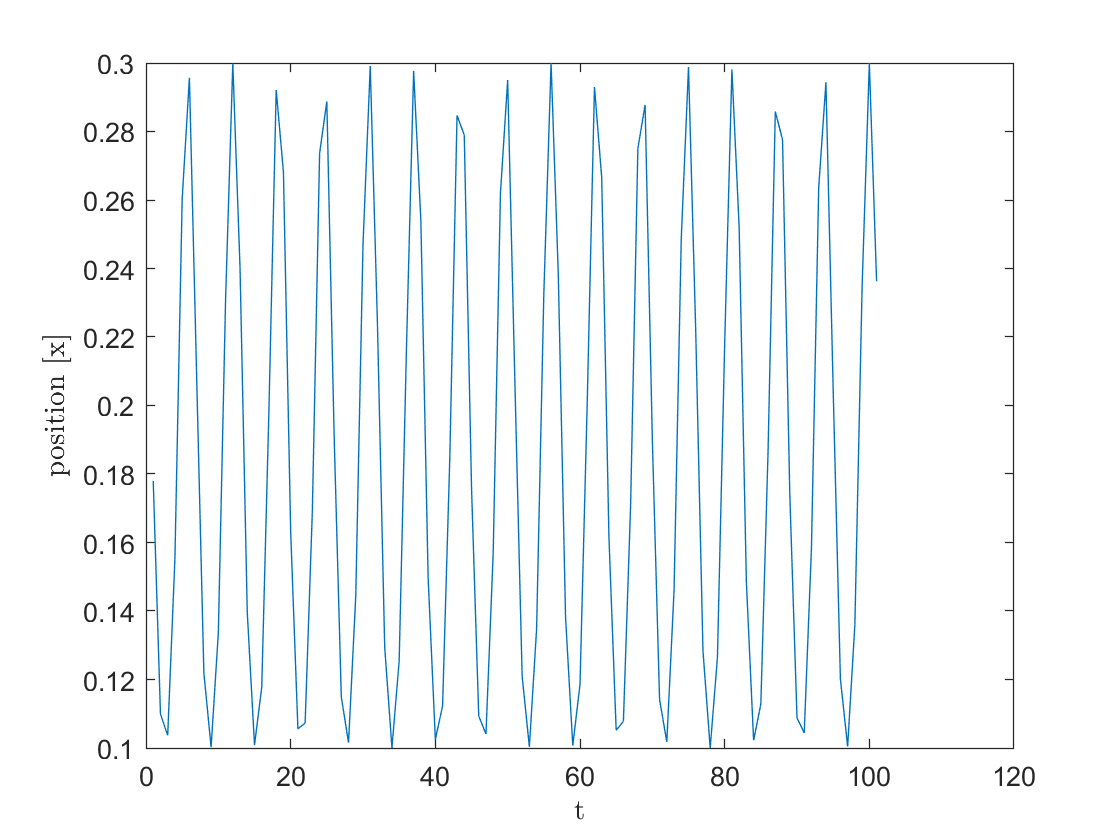

plt1 = plot(results(:,1),results(:,2));
xlabel('t', 'Interpreter','latex')
ylabel('position [x]', 'Interpreter','latex')
saveas(plt1,"output_position.png")

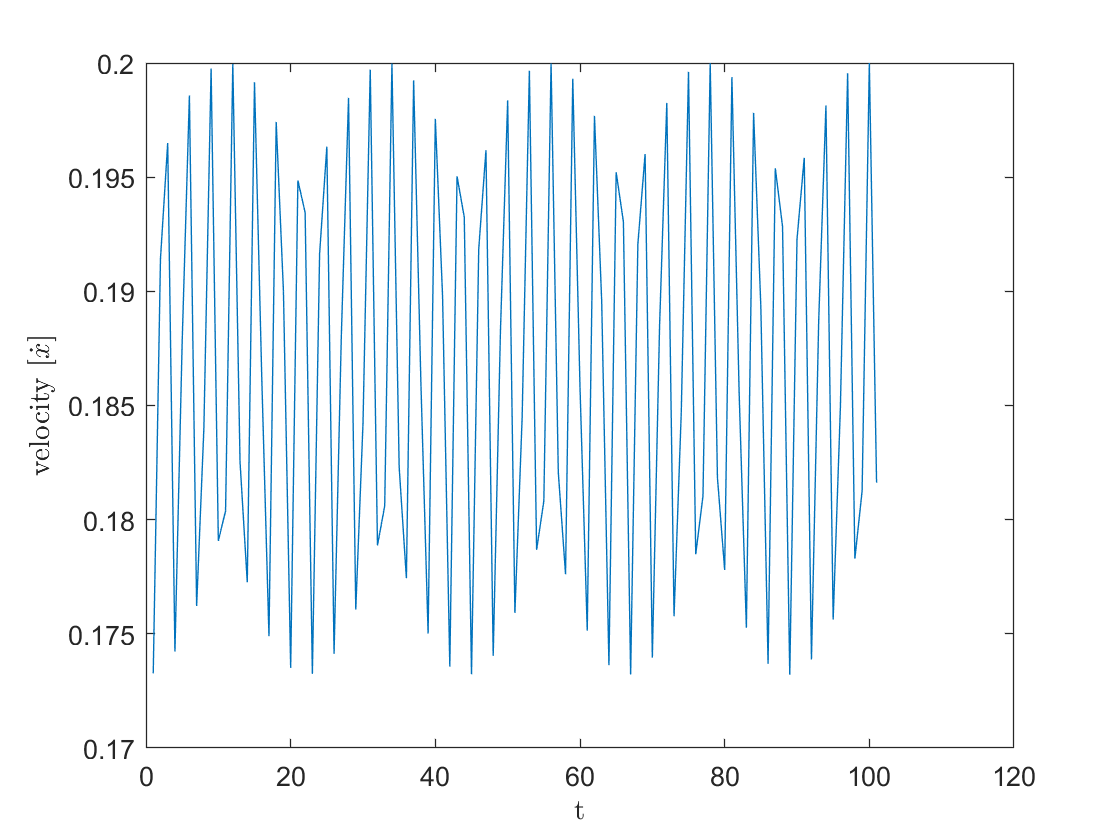

plt2 = plot(results(:,1),results(:,3));
xlabel('t', 'Interpreter','latex')
ylabel('velocity [$\dot{x}$]', 'Interpreter','latex')
saveas(plt2,"output_velocity.png")

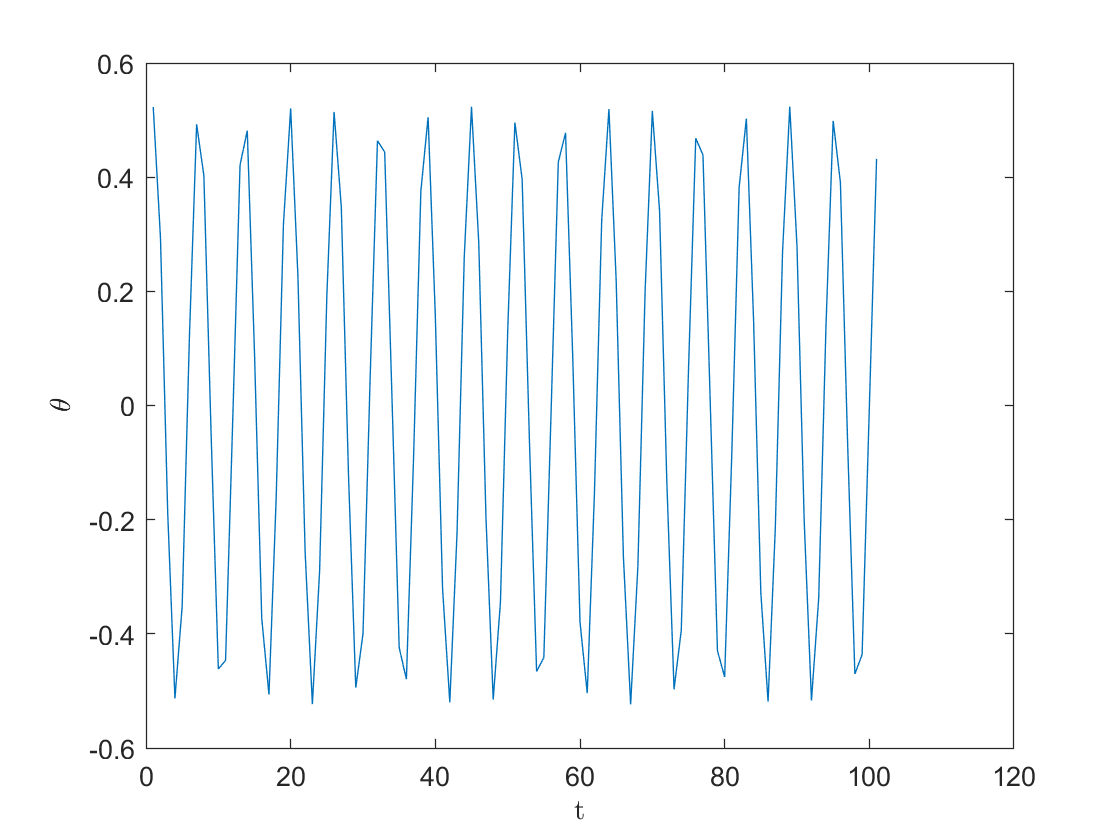

plt3 = plot(results(:,1),results(:,4));
xlabel('t', 'Interpreter','latex')
ylabel('$\theta$', 'Interpreter','latex')
saveas(plt3,"output_theta.png")

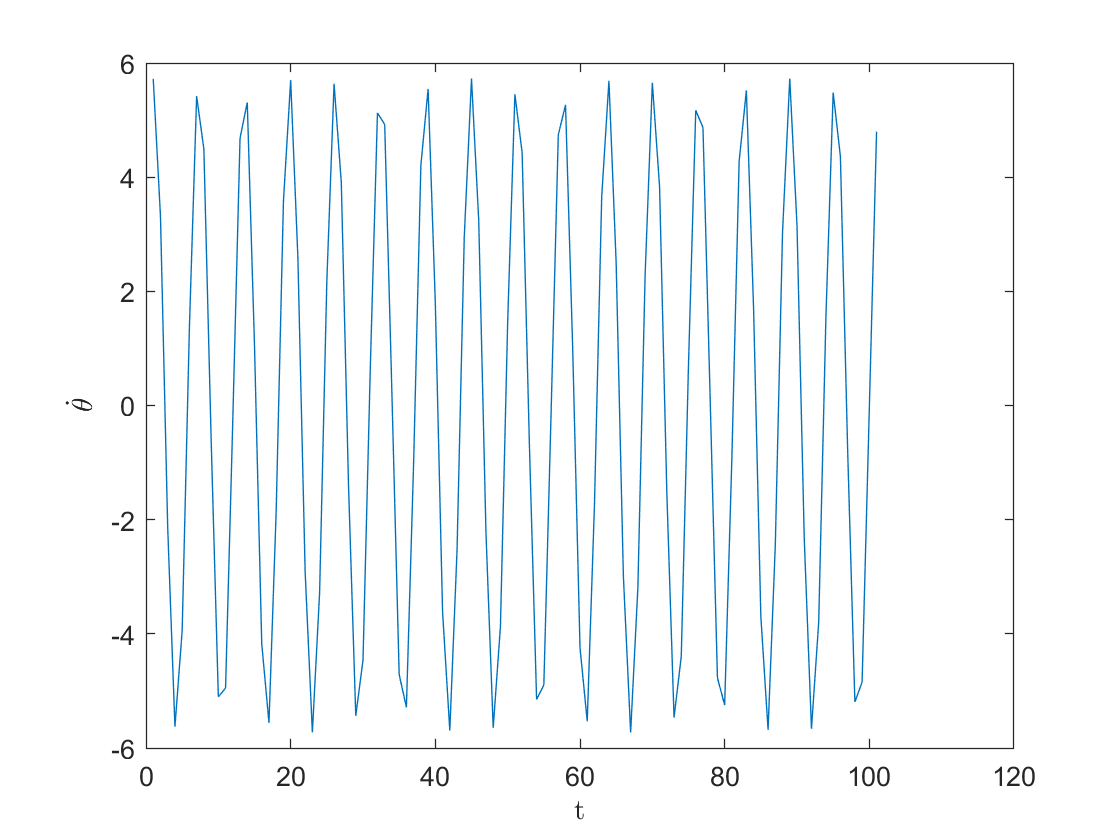

plt4 = plot(results(:,1),results(:,5));
xlabel('t', 'Interpreter','latex')
ylabel('$\dot{\theta}$', 'Interpreter','latex')
saveas(plt4,"output_theta_dot.png")

function P = constraint(u, a, b, phi)
theta = u(1);
d = u(2);

P = [a * cos(phi) + b * cos(theta) - d
    a * sin(phi) - b * sin(theta)];
end

function P = jacobian(u, b)
theta = u(1);
P = [b * -sin(theta), -1
    -b * cos(theta), 0];
end